# Proyecto de aplicación de método numéricos

## Autores:

### Funciones Auxiliares

function acc = derivada5p(h, vel)
    % Calcular la aceleración usando la fórmula de diferenciación de 5 puntos
    % h: paso de tiempo
    % vel: vector de velocidad angular
    
    n = length(vel);
    acc = zeros(n, 1);
    
    % Fórmula de 5 puntos en el interior
    for i = 3:n-2
        acc(i) = (vel(i-2) - 8*vel(i-1) + 8*vel(i+1) - vel(i+2))/(12*h);
    end
    
    % Tratamiento de bordes
    % Primer punto - Diferencia hacia adelante
    acc(1) = (-3*vel(1) + 4*vel(2) - vel(3))/(2*h);
    
    % Segundo punto - Diferencia hacia adelante
    acc(2) = (-3*vel(2) + 4*vel(3) - vel(4))/(2*h);
    
    % Penúltimo punto - Diferencia hacia atrás
    acc(n-1) = (3*vel(n-1) - 4*vel(n-2) + vel(n-3))/(2*h);
    
    % Último punto - Diferencia hacia atrás
    acc(n) = (3*vel(n) - 4*vel(n-1) + vel(n-2))/(2*h);
end

function acc = segundaDerivada(h, pos)
    % Calcular la aceleración usando la fórmula de la segunda derivada directa
    % h: paso de tiempo
    % pos: vector de posición angular (yaw)
    
    n = length(pos);
    acc = zeros(n, 1);
    
    % Fórmula de segunda derivada en el interior
    for i = 2:n-1
        acc(i) = (pos(i+1) - 2*pos(i) + pos(i-1))/(h^2);
    end
    
    % Tratamiento de bordes
    % Usar la fórmula del punto interior para el primer y último punto
    acc(1) = (pos(3) - 2*pos(2) + pos(1))/(h^2);
    acc(n) = (pos(n) - 2*pos(n-1) + pos(n-2))/(h^2);
end

### Cálculo aceleración angular

clear all;
close all;
clc;

% Cargar datos
load('DLCtest_data.mat');

% Conversión de unidades a SI
vel_long = vel_long/3.6;  % Convertir km/h a m/s
h = 0.002;  % Tiempo de muestreo en segundos

% Convertir de grados a radianes
beta = deg2rad(beta);
beta_rate = deg2rad(beta_rate);
delta = deg2rad(delta);
yaw = deg2rad(yaw);
yaw_rate = deg2rad(yaw_rate);

% Cálculo de aceleración con derivada de 5 puntos
acc_d5 = derivada5p(h, yaw_rate');

% Cálculo de aceleración con segunda derivada
acc_2d = segundaDerivada(h, yaw');

% Datos reales de aceleración
yaw_acc_real = yaw_acc';  % rad/s^2

% Vector de tiempo para gráficas
t = 0:h:(length(beta)*h - h);

% Visualización de resultados
figure;
subplot(2,1,1);
plot(t, acc_d5, 'r-', 'LineWidth', 1.2);
hold on;
plot(t, acc_2d, 'b-', 'LineWidth', 1.2);
plot(t, yaw_acc_real, 'k--', 'LineWidth', 1.5);
grid on;
title('Comparación de métodos de diferenciación numérica');
xlabel('Tiempo (s)');
ylabel('Aceleración angular (rad/s²)');
legend('Derivada 5 puntos', 'Segunda derivada', 'Datos reales');

% Cálculo del error
error_d5 = yaw_acc_real - acc_d5;
error_2d = yaw_acc_real - acc_2d;

subplot(2,1,2);
plot(t, error_d5, 'r-', 'LineWidth', 1.2);
hold on;
plot(t, error_2d, 'b-', 'LineWidth', 1.2);
grid on;
title('Error de estimación');
xlabel('Tiempo (s)');
ylabel('Error (rad/s²)');
legend('Error derivada 5 puntos', 'Error segunda derivada');


% Cálculo del coeficiente de determinación R²
% Para derivada de 5 puntos
St_d5 = sum((yaw_acc_real - mean(yaw_acc_real)).^2);
Sr_d5 = sum((yaw_acc_real - acc_d5).^2);
R2_d5 = (St_d5 - Sr_d5) / St_d5;

% Para segunda derivada
St_2d = sum((yaw_acc_real - mean(yaw_acc_real)).^2);
Sr_2d = sum((yaw_acc_real - acc_2d).^2);
R2_2d = (St_2d - Sr_2d) / St_2d;

% Mostrar resultados
% fprintf('Coeficiente de determinación R² para derivada de 5 puntos: %.4f\n', R2_d5);
% fprintf('Coeficiente de determinación R² para segunda derivada: %.4f\n', R2_2d);

% También podemos calcular el RMSE (Error cuadrático medio)
RMSE_d5 = sqrt(mean((yaw_acc_real - acc_d5).^2));
RMSE_2d = sqrt(mean((yaw_acc_real - acc_2d).^2));

% fprintf('RMSE para derivada de 5 puntos: %.4f\n', RMSE_d5);
% fprintf('RMSE para segunda derivada: %.4f\n', RMSE_2d);

### Determinación de los paramétros del modelo mediante RL

% Parámetros conocidos del modelo
m = 1507;  % masa del vehículo [kg]
Iz = 2995.02;  % momento de inercia [kg*m^2]

% Construcción de matrices para la regresión
n = length(t);
A = zeros(2*n, 4);  % Matriz de coeficientes
b = zeros(2*n, 1);  % Vector de términos independientes

% Llenado de matrices con las ecuaciones reorganizadas
for i = 1:n
    v = vel_long(i);
    
    % Ecuación para beta_dot (reorganizada)
    % beta_dot + r = -(cf+cr)/(m*v)*beta + (cf/(m*v))*delta
    A(i, 1) = -beta(i)/v;  % Coeficiente para (cf+cr)/m
    A(i, 2) = 0;          % Coeficiente para (lf*cf-lr*cr)/m
    A(i, 3) = delta(i)/v;  % Coeficiente para cf/m
    A(i, 4) = 0;          % Coeficiente para lf*cf/m
    b(i) = beta_rate(i) + yaw_rate(i);
    
    % Ecuación para yaw_acc (reorganizada)
    % r_dot + (r/v) = -(lf*cf-lr*cr)/Iz*beta - (lf^2*cf+lr^2*cr)/(Iz*v)*r + (lf*cf/Iz)*delta
    A(i+n, 1) = 0;            % Coeficiente para (cf+cr)/m
    A(i+n, 2) = -beta(i);     % Coeficiente para (lf*cf-lr*cr)/Iz
    A(i+n, 3) = 0;            % Coeficiente para cf/m
    A(i+n, 4) = delta(i);     % Coeficiente para lf*cf/Iz
    b(i+n) = yaw_acc_real(i) + yaw_rate(i)/v;
end

% Resolución del sistema de ecuaciones sobredeterminado usando mínimos cuadrados
p = A\b;  % Equivalente a p = inv(A'*A)*A'*b pero más eficiente

% Extracción de los parámetros calculados
cf_plus_cr_over_m = p(1);
lf_cf_minus_lr_cr_over_Iz = p(2);
cf_over_m = p(3);
lf_cf_over_Iz = p(4);

% Cálculo de los parámetros físicos del modelo
cf = cf_over_m * m;
lf = lf_cf_over_Iz * Iz / cf;
cr = cf_plus_cr_over_m * m - cf;
lr = (lf*cf - lf_cf_minus_lr_cr_over_Iz * Iz) / cr;

% Mostrar los parámetros estimados
fprintf('Parámetros estimados del modelo:\n');

Parámetros estimados del modelo:


fprintf('cf = %.2f N/rad\n', cf);

cf = 8484.02 N/rad


fprintf('cr = %.2f N/rad\n', cr);

cr = 149313.03 N/rad


fprintf('lf = %.2f m\n', lf);

lf = 0.13 m


fprintf('lr = %.2f m\n', lr);

lr = 0.86 m


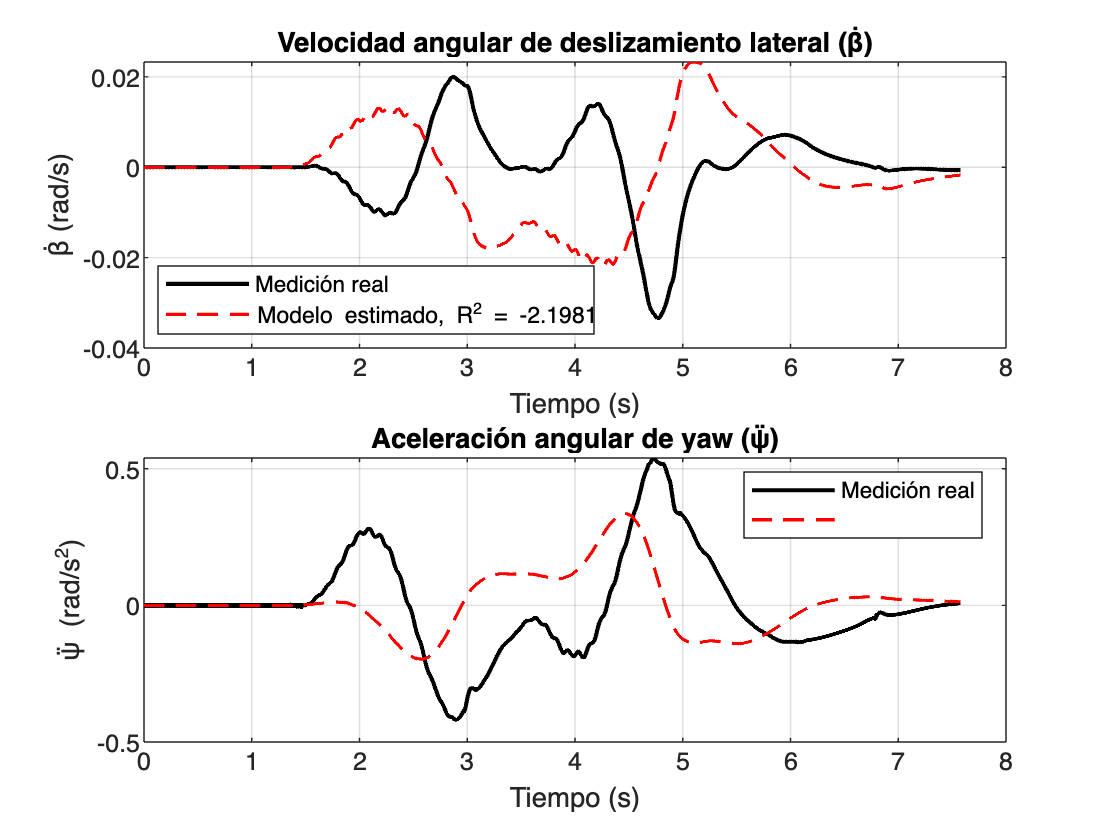


% Simulación con los parámetros estimados
beta_dot_est = zeros(n, 1);
yaw_acc_est = zeros(n, 1);

for i = 1:n
    v = vel_long(i);
    
    % Ecuaciones del modelo con los parámetros estimados
    beta_dot_est(i) = -(cf+cr)/(m*v)*beta(i) + ...
                      (-(lf*cf-lr*cr)/(m*v^2) - 1)*yaw_rate(i) + ...
                      (cf/(m*v))*delta(i);
    
    yaw_acc_est(i) = -(lf*cf-lr*cr)/Iz*beta(i) + ...
                     -(lf^2*cf+lr^2*cr)/(Iz*v)*yaw_rate(i) + ...
                     (lf*cf/Iz)*delta(i);
end

% Cálculo de R^2 para la validación del modelo
r2_beta_dot = 1 - sum((beta_rate - beta_dot_est).^2) / sum((beta_rate - mean(beta_rate)).^2);
r2_yaw_acc = 1 - sum((yaw_acc_real - yaw_acc_est).^2) / sum((yaw_acc_real - mean(yaw_acc_real)).^2);

% Visualización de resultados
figure(2);
subplot(2,1,1);
plot(t, beta_rate, 'k', 'LineWidth', 1.5);
hold on;
plot(t, beta_dot_est, 'r--', 'LineWidth', 1.2);
grid on;
title('Velocidad angular de deslizamiento lateral (β̇)');
xlabel('Tiempo (s)');
ylabel('β̇ (rad/s)');
legend('Medición real', ['Modelo estimado, R^2 = ' num2str(r2_beta_dot, '%.4f')], 'Location', 'best');

subplot(2,1,2);
plot(t, yaw_acc_real, 'k', 'LineWidth', 1.5);
hold on;
plot(t, yaw_acc_est, 'r--', 'LineWidth', 1.2);
grid on;
title('Aceleración angular de yaw (ψ̈)');
xlabel('Tiempo (s)');
ylabel('ψ̈ (rad/s^2)');
legend('Medición real', ['Modelo estimado, R^2 = ' num2str(r2_yaw_acc, '%.4f')], 'Location', 'best');

### Integración numérica mediante simpson 1/3

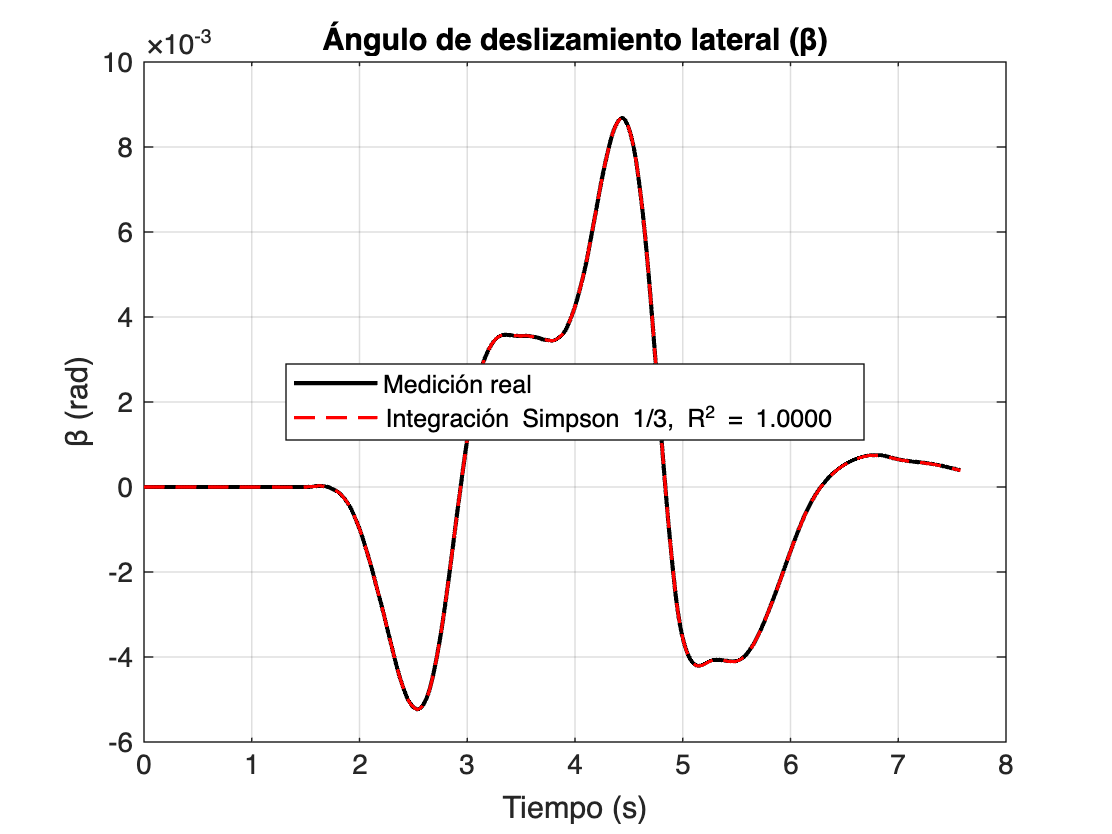

% Integración de la velocidad angular de deslizamiento
beta_simpson = zeros(size(beta));
beta_simpson(1) = beta(1);  % Condición inicial

% Aplicación de la regla de Simpson 1/3 para cada intervalo
for i = 3:2:length(t)
    % Para cada punto i, integramos desde 0 hasta t(i)
    h_simpson = t(2) - t(1);  % Paso de integración
    n_simpson = i;  % Número de puntos hasta el instante actual
    
    if mod(n_simpson-1, 2) == 0  % Verificar si tenemos un número par de subintervalos
        % Aplicar Simpson 1/3
        suma = beta_rate(1);
        
        % Términos con coeficiente 4 (índices impares)
        for j = 2:2:n_simpson-1
            suma = suma + 4*beta_rate(j);
        end
        
        % Términos con coeficiente 2 (índices pares)
        for j = 3:2:n_simpson-2
            suma = suma + 2*beta_rate(j);
        end
        
        suma = suma + beta_rate(n_simpson);
        beta_simpson(i) = beta(1) + (h_simpson/3)*suma;
    else
        % Si no tenemos número par de subintervalos, usamos el valor anterior
        % y agregamos un trapecio para el último intervalo
        if i > 2
            beta_simpson(i) = beta_simpson(i-1) + ...
                              h_simpson*(beta_rate(i-1) + beta_rate(i))/2;
        end
    end
    
    % Si hay un punto adicional, usamos trapecio para completar
    if i < length(t)
        beta_simpson(i+1) = beta_simpson(i) + h_simpson*(beta_rate(i) + beta_rate(i+1))/2;
    end
end

% Cálculo de R^2 para la integración
r2_beta_int = 1 - sum((beta - beta_simpson).^2) / sum((beta - mean(beta)).^2);

% Visualización de resultados
figure(3);
plot(t, beta, 'k', 'LineWidth', 1.5);
hold on;
plot(t, beta_simpson, 'r--', 'LineWidth', 1.2);
grid on;
title('Ángulo de deslizamiento lateral (β)');
xlabel('Tiempo (s)');
ylabel('β (rad)');
legend('Medición real', ['Integración Simpson 1/3, R^2 = ' num2str(r2_beta_int, '%.4f')], 'Location', 'best');

### Método de Heun para ecuaciones diferenciales

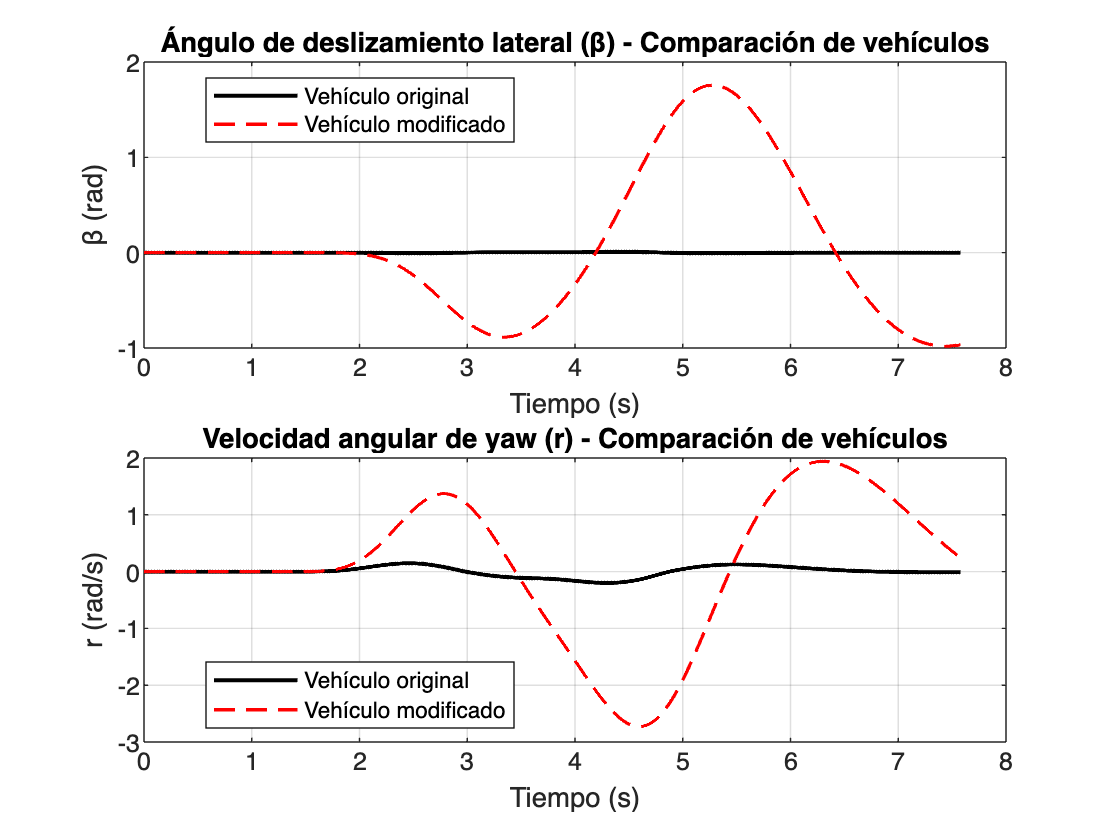

% Parámetros del nuevo automóvil
m_nuevo = 1860;        % kg
Iz_nuevo = 3420;        % kg·m^2
cf_nuevo = 12200;       % N/rad
cr_nuevo = 12200;       % N/rad
lf_nuevo = 1.23;        % m
lr_nuevo = 1.55;        % m

% Condiciones iniciales
beta_heun = zeros(size(t));
yaw_rate_heun = zeros(size(t));

% Método de Heun para resolver el sistema de ecuaciones diferenciales
for i = 1:length(t)-1
    % Modelo de bicicleta para el nuevo vehículo
    % Paso predictor (Euler explícito)
    k1_beta = -(cf_nuevo+cr_nuevo)/(m_nuevo*vel_long(i))*beta_heun(i) + ...
              (-(lf_nuevo*cf_nuevo-lr_nuevo*cr_nuevo)/(m_nuevo*vel_long(i)^2) - 1)*yaw_rate_heun(i) + ...
              (cf_nuevo/(m_nuevo*vel_long(i)))*delta(i);
    
    k1_yaw_rate = -(lf_nuevo*cf_nuevo-lr_nuevo*cr_nuevo)/Iz_nuevo*beta_heun(i) + ...
                   -(lf_nuevo^2*cf_nuevo+lr_nuevo^2*cr_nuevo)/(Iz_nuevo*vel_long(i))*yaw_rate_heun(i) + ...
                   (lf_nuevo*cf_nuevo/Iz_nuevo)*delta(i);
    
    beta_pred = beta_heun(i) + h*k1_beta;
    yaw_rate_pred = yaw_rate_heun(i) + h*k1_yaw_rate;
    
    % Paso corrector
    k2_beta = -(cf_nuevo+cr_nuevo)/(m_nuevo*vel_long(i+1))*beta_pred + ...
              (-(lf_nuevo*cf_nuevo-lr_nuevo*cr_nuevo)/(m_nuevo*vel_long(i+1)^2) - 1)*yaw_rate_pred + ...
              (cf_nuevo/(m_nuevo*vel_long(i+1)))*delta(i+1);
    
    k2_yaw_rate = -(lf_nuevo*cf_nuevo-lr_nuevo*cr_nuevo)/Iz_nuevo*beta_pred + ...
                   -(lf_nuevo^2*cf_nuevo+lr_nuevo^2*cr_nuevo)/(Iz_nuevo*vel_long(i+1))*yaw_rate_pred + ...
                   (lf_nuevo*cf_nuevo/Iz_nuevo)*delta(i+1);
    
    % Actualización final (método de Heun)
    beta_heun(i+1) = beta_heun(i) + h*(k1_beta + k2_beta)/2;
    yaw_rate_heun(i+1) = yaw_rate_heun(i) + h*(k1_yaw_rate + k2_yaw_rate)/2;
end

% Visualización de resultados del método de Heun
figure(4);
subplot(2,1,1);
plot(t, beta, 'k', 'LineWidth', 1.5);
hold on;
plot(t, beta_heun, 'r--', 'LineWidth', 1.2);
grid on;
title('Ángulo de deslizamiento lateral (β) - Comparación de vehículos');
xlabel('Tiempo (s)');
ylabel('β (rad)');
legend('Vehículo original', 'Vehículo modificado', 'Location', 'best');

subplot(2,1,2);
plot(t, yaw_rate, 'k', 'LineWidth', 1.5);
hold on;
plot(t, yaw_rate_heun, 'r--', 'LineWidth', 1.2);
grid on;
title('Velocidad angular de yaw (r) - Comparación de vehículos');
xlabel('Tiempo (s)');
ylabel('r (rad/s)');
legend('Vehículo original', 'Vehículo modificado', 'Location', 'best');

Función de Transferencia y Newton Raphson

% Velocidad constante
v_const = 27.77;  % m/s (100 km/h)

% Parámetros del automóvil modificado
m = m_nuevo;
Iz = Iz_nuevo;
cf = cf_nuevo;
cr = cr_nuevo;
lf = lf_nuevo;
lr = lr_nuevo;

% Coeficientes para la función de transferencia
a = (cf + cr) / (m * v_const);
b = (lf * cf - lr * cr) / (m * v_const^2);
c = (lf * cf - lr * cr) / Iz;
d = (lf^2 * cf + lr^2 * cr) / (Iz * v_const);
e = cf / (m * v_const);
f = lf * cf / Iz;

% Coeficientes del denominador y numerador
% G(s) = (Cs + D) / (s^2 + As + B)
A = a + d;
B = a*d - c*b - c;
C = e;
D = e*d - f*b;

% Mostrar la función de transferencia
fprintf('\nFunción de transferencia G(s) = β(s)/δ(s):\n');


Función de transferencia G(s) = β(s)/δ(s):


fprintf('G(s) = (%.4f·s + %.4f) / (s^2 + %.4f·s + %.4f)\n', C, D, A, B);

G(s) = (0.2362·s + 0.1307) / (s^2 + 0.9754·s + 1.3760)



% Método de Newton-Raphson para encontrar las raíces del denominador
% Función polinómica del denominador: s^2 + As + B
f_denom = @(s) s^2 + A*s + B;
% Derivada de la función
df_denom = @(s) 2*s + A;

% Configuración del método
s0 = -1;  % Valor inicial
tol = 0.001;  % Tolerancia (0.1%)
max_iter = 100;

% Variables para almacenar resultados
iter = 0;
s = s0;
error_rel = 1;

% Iteraciones del método de Newton-Raphson
fprintf('\nMétodo de Newton-Raphson para encontrar las raíces:\n');


Método de Newton-Raphson para encontrar las raíces:


fprintf('Iter\t s\t\t f(s)\t\t Error relativo\n');

Iter	 s		 f(s)		 Error relativo



while error_rel > tol && iter < max_iter
    s_old = s;
    s = s_old - f_denom(s_old) / df_denom(s_old);
    error_rel = abs((s - s_old) / s);
    iter = iter + 1;
    fprintf('%d\t %.6f\t %.6e\t %.6e\n', iter, s, f_denom(s), error_rel);
end

1	 0.366962	 1.868585e+00	 3.725078e+00
2	 -0.726241	 1.195094e+00	 1.505289e+00
3	 1.778504	 6.273751e+00	 1.408344e+00
4	 0.394291	 1.916045e+00	 3.510635e+00
5	 -0.691943	 1.179905e+00	 1.569832e+00
6	 2.196194	 8.341333e+00	 1.315065e+00
7	 0.642218	 2.414840e+00	 2.419700e+00
8	 -0.426395	 1.141935e+00	 2.506156e+00
9	 -9.743748	 8.681306e+01	 9.562391e-01
10	 -5.054229	 2.199159e+01	 9.278407e-01
11	 -2.646331	 5.797973e+00	 9.099006e-01
12	 -1.303371	 1.803540e+00	 1.030373e+00
13	 -0.197849	 1.222179e+00	 5.587695e+00
14	 -2.306319	 4.445645e+00	 9.142142e-01
15	 -1.084077	 1.493875e+00	 1.127449e+00
16	 0.168329	 1.568522e+00	 7.440219e+00
17	 -1.027182	 1.429247e+00	 1.163875e+00
18	 0.297405	 1.754532e+00	 4.453811e+00
19	 -0.820016	 1.248630e+00	 1.362683e+00
20	 1.058526	 3.528918e+00	 1.774677e+00
21	 -0.082632	 1.302240e+00	 1.381016e+01
22	 -1.690162	 2.584155e+00	 9.511102e-01
23	 -0.615658	 1.154559e+00	 1.745294e+00
24	 3.894954	 2.034562e+01	 1.158066e+00
25	 1.5737


% La segunda raíz se puede calcular usando la fórmula cuadrática
s1 = s;  % Primera raíz obtenida por Newton-Raphson
s2 = (-A - s1);  % Segunda raíz (usando la relación entre raíces y coeficientes)

fprintf('\nRaíces del denominador (polos):\n');


Raíces del denominador (polos):


fprintf('s1 = %.6f\n', s1);

s1 = -0.835332


fprintf('s2 = %.6f\n', s2);

s2 = -0.140019



% Análisis del tipo de amortiguamiento
discriminante = A^2 - 4*B;
fprintf('\nDiscriminante = %.6f\n', discriminante);


Discriminante = -4.552720



if discriminante > 0
    fprintf('Sistema SOBREAMORTIGUADO: Los polos son reales y distintos.\n');
elseif discriminante == 0
    fprintf('Sistema CRÍTICAMENTE AMORTIGUADO: Los polos son reales e iguales.\n');
else
    fprintf('Sistema SUBAMORTIGUADO: Los polos son complejos conjugados.\n');
end

Sistema SUBAMORTIGUADO: Los polos son complejos conjugados.
